# Bipedal Leg Simulation

#### Import the Necessary Imports

 
% Import the Python module containing your function
%python = py.importlib.import_module('patty_code');
%!pip install numpy
%!pip install scipy
clear
clc

## what to fix!

%reverse angles in simulation
%fix what happens if 2 consecutive angles are the same
%display what frame you are showing
%have it work with python
%make it so you are only playing around with angles in python script
%reverse motor ID and angle
%put double on top and single leg sim on bottom

## Angle Arrays 

% Call the Python function
% angle_tuples = python.angle_arrays();
angle_tuples = {
    {[1499, 11], [2200, 12], [1499, 13], [2200, 14], [1499, 21], [2200, 22], [1499, 23], [2200, 24]}; 
    {[1499, 11], [2200, 12], [1499, 13], [2200, 14], [1699, 21], [2200, 22], [1499, 23], [2200, 24]}; 
    {[200, 11], [2200, 12], [1499, 13], [2100, 14], [1499, 21], [3200, 22], [1499, 23], [2200, 24]}
};

% Convert the Python list of arrays of tuples to a MATLAB cell array
angles_cell = cell(length(angle_tuples), 1);
for i = 1:length(angle_tuples)
    angles_cell{i} = cell(angle_tuples{i});
end

% Transform angle_tuples to contain only the first elements of each tuple
converted_angles_cell = cellfun(@(x) cellfun(@(y) y(1), x), angle_tuples, 'UniformOutput', false);

## Dual Leg Simulation

 
%%%%%% make angles cell %%%%%% {hip, knee}
angles_cell1 = {
    {0, -90};       %frame 1
    {60, -80};      %frame 2
    {45, -40};      %frame 3
    {30, 0};        %frame 4
    {0,0};          %frame 5
    {0, -5};        %frame 6
    {-10, -20};     %frame 7
    {-30, -60}      %frame 8
};


angles_cell2 = {
    {0,0};          %frame 1
    {0, -5};        %frame 2
    {-10, -20};     %frame 3
    {-30, -60};     %frame 4
    {0, -90};       %frame 5
    {60, -80};      %frame 6
    {45, -40};      %frame 7
    {30, 0}         %frame 8
};

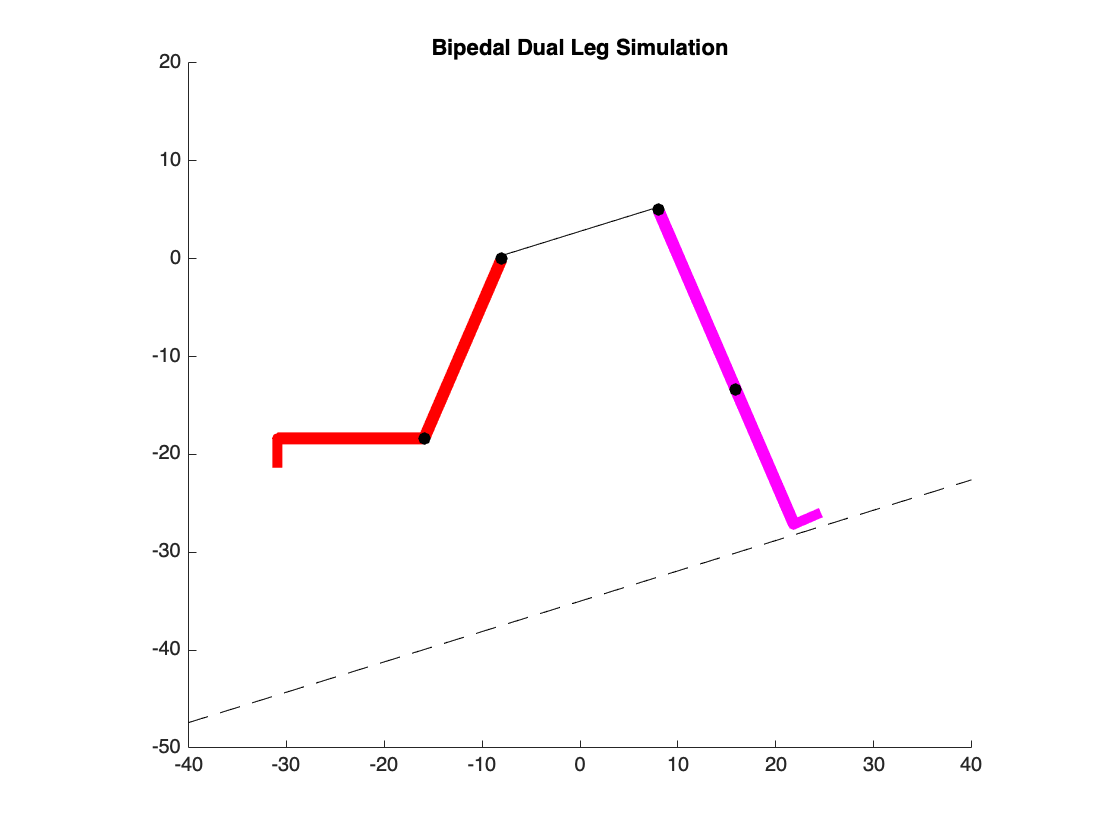

 

%%%%%% LOOP THROUGH %%%%%
figure;
axis equal;
axis manual;
axis([-40 40 -50 20]);

title('Bipedal Dual Leg Simulation');
% Define floor line
x_range1 = [-40, 40];
y_values1 = (0.31) * x_range1 + (-35);
hold on;
plot(x_range1, y_values1, 'k--'); % Floor line
x_range2 = [-8, 8];
y_values2 = (0.31) * x_range2 + (2.8);
plot(x_range2, y_values2, 'k.-'); % Body line

% Set the axis limits after plotting the floor line
xlim([-40 40]);
ylim([-50 20]);

%%%%%% LOOP THROUGH %%%%%
start_hip_angle1 = 0;
start_knee_angle1 = 0;
start_hip_angle2 = 0;
start_knee_angle2 = 0;
angular_velocity = 3;  %[deg/sec]???
num_loop = 3;

for k = 1 : num_loop
    for i = 1 : size(angles_cell1,1)
        % Get the angles from the cell array
        angles1 = angles_cell1{i};
        angles2 = angles_cell2{i};
    
        %%%%%%% UNCOMENT IF CALLING FUNCTION FOR ANGLES %%%%%%%%
        %angles = converted_angles_cell{i};
        %goal_hip_angle1 = motor2deg(angles(3));
        %goal_knee_angle1 = motor2deg(angles(4));
        %goal_hip_angle2 = motor2deg(angles(7));
        %goal_knee_angle2 = motor2deg(angles(8));
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
        %%%%%%% UNCOMENT IF MAKING OWN ANGLE CELL ARRAY %%%%%%%%
        goal_hip_angle1 = angles1{1};
        goal_knee_angle1 = angles1{2};
        goal_hip_angle2 = angles2{1};
        goal_knee_angle2 = angles2{2};
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
       
        % Call the move2angle function with the extracted angles
        move2angle_dual_leg(start_hip_angle1, start_knee_angle1, goal_hip_angle1, goal_knee_angle1, start_hip_angle2, start_knee_angle2, goal_hip_angle2, goal_knee_angle2, angular_velocity);
    
        % reset start angles
        start_hip_angle1 = goal_hip_angle1;
        start_knee_angle1 = goal_knee_angle1;
        start_hip_angle2 = goal_hip_angle2;
        start_knee_angle2 = goal_knee_angle2;
    end
end

Display to copy and paste :)

 
new_tuples = angles2tuples(angles_cell1, angles_cell2);

## Single Leg Simulation

 
%%%%%% make angles cell %%%%%% {hip, knee}
angles_cell = {
    {50, -80}; 
    {45, 0};
    {-40, -5};
    {-30, -60};
    {0, -90}
};

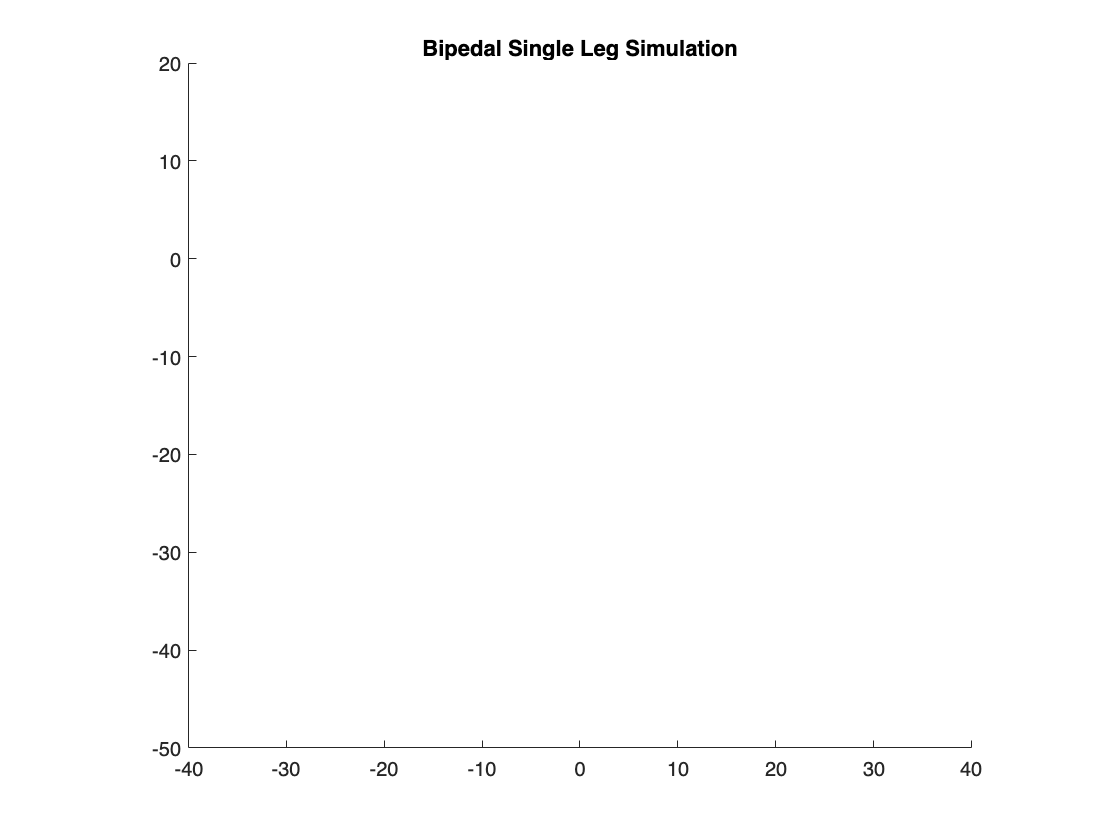

 

figure;
axis equal;
xlim([-40, 40]); % Set the x-axis limits
ylim([-50, 20]); % Set the y-axis limits
title('Bipedal Single Leg Simulation');
%%%%%% LOOP THROUGH %%%%%
start_hip_angle = 0;
start_knee_angle = 0;
angular_velocity = 3;  %[deg/sec]???
num_loop = 3;

for k = 1 : num_loop
    for i = 1 : size(angles_cell,1)
        % Get the angles from the cell array
        
        %%%%%%% UNCOMENT IF CALLING FUNCTION FOR ANGLES %%%%%%%%
        %angles = converted_angles_cell{i};
        %goal_hip_angle = motor2deg(angles(3));
        %goal_knee_angle = motor2deg(angles(4));
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
        %%%%%%% UNCOMENT IF MAKING OWN ANGLE CELL ARRAY %%%%%%%%
        angles = angles_cell{i};
        goal_hip_angle = angles{1};
        goal_knee_angle = angles{2};
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
       
        % Call the move2angle function with the extracted angles
        move2angle(start_hip_angle, start_knee_angle, goal_hip_angle, goal_knee_angle, angular_velocity);
    
        % reset start angles
        start_hip_angle = goal_hip_angle;
        start_knee_angle = goal_knee_angle;
    end
end